# Model Overfitting and Regularization

*Kirsten Peterson - 2023*

We often make inferences about complex systems by fitting statistical models to observed data.  For instance, we may assess a brain region's computational role by testing if its activity varies with task conditions, or also by testing how its activity fluctuates with the activities of other regions.  Models may be simple, attempting to relate few variables (ex. a few dimensions of trial features), or they may be complicated, incorporating many variables (ex. hundreds of other regions' activities).  Models can also become more complex by allowing for interactions between variables, nonlinear relationships, or otherwise high degrees of flexibility.  Allowing for a greater level of complexity may be needed for some research questions, but it also puts the model at higher risk for overfitting to noise.  Regularization methods can help overcome this.  This lesson will demonstrate overfitting and regularization in regression models only, but the concepts can also be applied to other types of statistical models (ex. artificial neural networks).

## What is model overfitting?

Overfitting occurs when a model is overly sensitive to the noise in a training dataset, often because the model is allowed to be too flexible for the given data.  In minimizing the error between model estimates and training data, the model then reflects random noise in addition to the true underlying pattern.  This means that its coefficients will be inaccurate and unstable and that the model will make poor predictions when given new data.  

Since data with many variables can be difficult to visualize, we will first illustrate the problem of overfitting using polynomial curve fitting.  Unlike in the curve fitting class where we used Matlab's *fit* function, here we manually create regressors for all polynomial terms and use linear regression to assign a coefficient to each term.  For any value of x, y is given by $y=\beta_0 +\beta_1 x+\beta_2 x^2 +\beta_3 x^3 \cdots +\beta_n x^n +\varepsilon$.  This method is not limited to representing polynomial functions, but can model the curves of any class of function.  Here, for instance, we define the true x-y relationship as a sine wave.  We use R^2 (coefficient of determination) to assess the similarity of the estimated curve to the true curve.

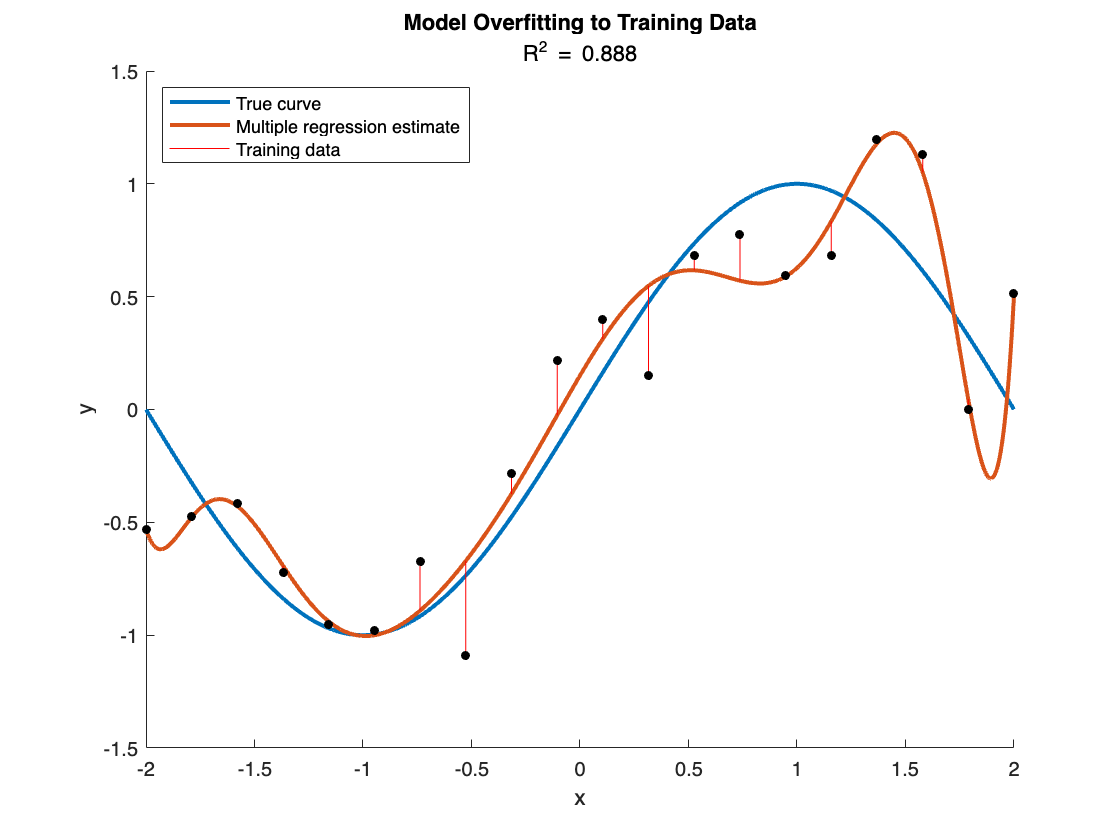

rng(1230,'twister'); % Generate the same random numbers every time

% Function: Generate a matrix of polynomial regressors corresponding to the
% values of 'x' for 'nrVars' polynomial terms.
polyRegressors = @(x,nrVars) [ones(1,length(x)); zscore(repmat(x,nrVars,1).^((1:nrVars)'),0,2)];
% 1. Duplicate x (row vector) into nrVars rows
% 2. Raise each row to the power of {1, 2, 3, ... nrVars}
% 3. Z-score each row (i.e. scale the values to have mean=0 and SD=1;
% necessary for regularization)
% 4. Append a row of ones to the top to model the constant term

% Number of predictor variables (polynomial terms) to include in the model
% (excluding the constant term)
nrVars = 10;

xMin = -2;
xMax = 2;
dx = .001;
xCurve = xMin:dx:xMax; % A vector of many x values, for plotting curves
polyReg = polyRegressors(xCurve,nrVars); % Value of each polynomial term 
% (predictor variable/regressor) at each x in xCurve
yCurveTrue = sin(pi/2*xCurve); % Use a sine wave as the true curve

% Number of observations and noise level in simulated data sample
nrObs = 20;
noiseLevel = .5;

% Sample x values and indices into 'curve' data vectors for downsampling
xSample = linspace(xMin,xMax,nrObs);
sampleIdx = ismember(round(xCurve,-log10(dx)),round(xSample,-log10(dx)));
polyRegSample = polyReg(:,sampleIdx); % Downsampled regressors
% Simulated sample y values- true values plus noise
ySample = yCurveTrue(sampleIdx) + randn(1,nrObs)*noiseLevel;

% Fit regression model to the data sample
estBetas = regress(ySample',polyRegSample');
yCurveEst = sum(estBetas.*polyReg); % Model estimates at many values
ySampleEst = sum(estBetas.*polyRegSample); % Model estimates at sampled values

% Plot the true curve, data samples, and model estimate
figure
hold on
plot(xCurve,yCurveTrue,LineWidth=2)
plot(xCurve,yCurveEst,LineWidth=2)
for s = 1:nrObs
    plot([xSample(s),xSample(s)],[ySample(s),ySampleEst(s)],'r')
end
scatter(xSample,ySample,20,'k','filled')
ylim([-1.5,1.5])
xlabel('x')
ylabel('y')
title('Model Overfitting to Training Data')
subtitle(['R^2 = ',num2str(Rsquared(yCurveEst,yCurveTrue),3)])
legend({'True curve';'Multiple regression estimate';'Training data'},Location='northwest')

## Causes of overfitting

Some factors that can increase model overfitting are having too few datapoints for the number of predictor variables, having too much noise compared to the signal of interest, and having collinearity among regressors.  

If there are fewer datapoints than predictor variables, then the data is rank deficient and standard multiple regression cannot run.  (Regularization can overcome this lower limit on data samples, which is another benefit of the methods).  If there are an equal number of datapoints and predictors (and the regressors are full rank), then the regression model is able to fit every datapoint exactly.  However, this model estimate does not necessarily resemble the true system, as we can see below when we fit 11 beta coefficients (including constant) to 11 datapoints.  Adding more data improves model performance as it forces the model to compromise between points and better follow trends in the data.  Including even more data supplies the model with still more evidence for the true underlying pattern.

If the data has a higher level of noise compared to the signal or effect of interest, then the random noise will be able to exert more influence over the model.  We often have no control over the level of noise in our chosen type of data, but we can make up for noisy data or small effect sizes by collecting more data samples.  Note that when we refer to "noise", it is not necessarily measurement error but rather is any variability that the model cannot legitimately account for.

Collinearity means that two or more predictors in a regression model are highly correlated with each other.  This makes it difficult for the model to determine the individual effects of the correlated predictors on the dependent variable, and their estimated contributions can easily fluctuate in response to noise in the data.  This leads to unstable and inaccurate coefficients.  Because much information in the variables is redundant, the model may also assign a positive effect to one predictor and a negative effect to the other, sometimes with very large scales if their terms will mostly cancel out.

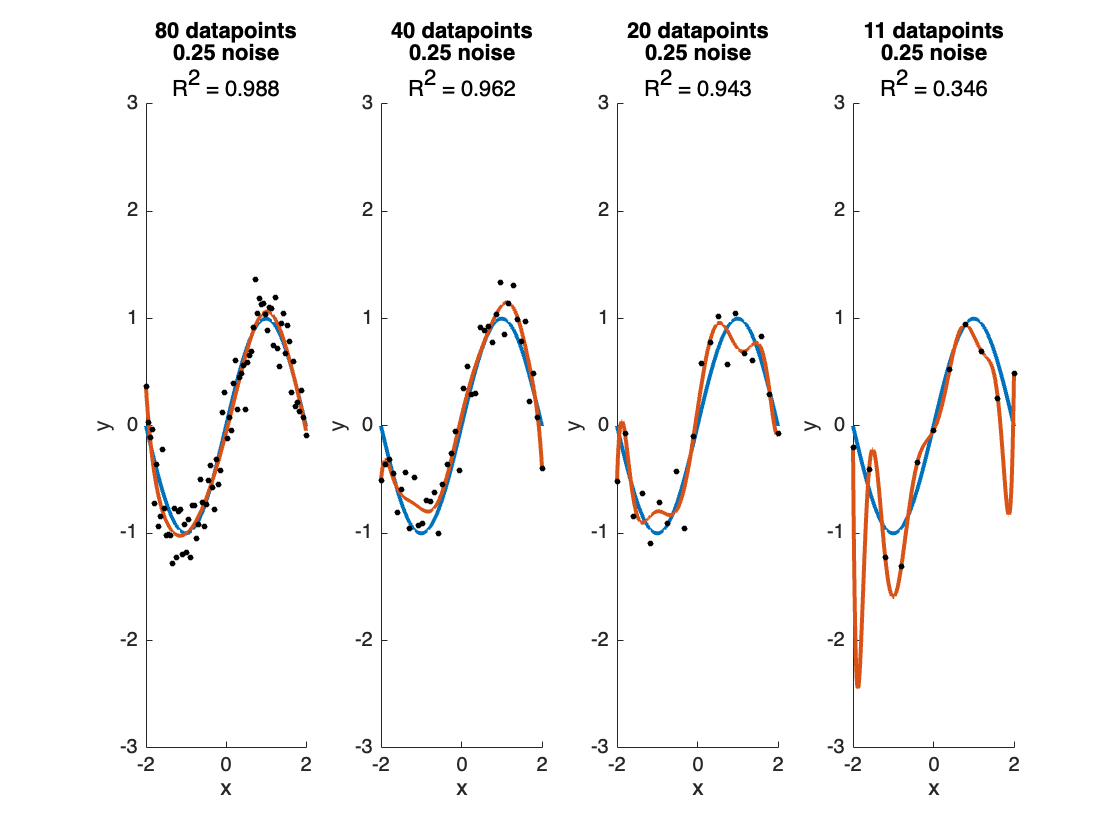

% Simulate data samples and fit models for different numbers of
% observations
nrObsList = [80,40,20,11];
noiseLevel = .25;
figure
tiledlayout(1,length(nrObsList))

for i = 1:length(nrObsList)
    nrObs = nrObsList(i);
    xSample = linspace(xMin,xMax,nrObs);
    sampleIdx = ismember(round(xCurve,-log10(dx)),round(xSample,-log10(dx)));
    polyRegSample = polyReg(:,sampleIdx);
    ySample = yCurveTrue(sampleIdx) + randn(1,nrObs)*noiseLevel;
    estBetas = regress(ySample',polyRegSample');
    yCurveEst = sum(estBetas.*polyReg);
    
    % Plot the true curve, data samples, and model estimate for each simulation
    nexttile
    hold on
    plot(xCurve,yCurveTrue,LineWidth=2)
    plot(xCurve,yCurveEst,LineWidth=2)
    scatter(xSample,ySample,10,'k','filled')
    ylim([-3,3])
    xlabel('x')
    ylabel('y')
    title({[num2str(nrObs),' datapoints'];[num2str(noiseLevel),' noise']})
    subtitle(['R^2 = ',num2str(Rsquared(yCurveEst,yCurveTrue),3)])
end

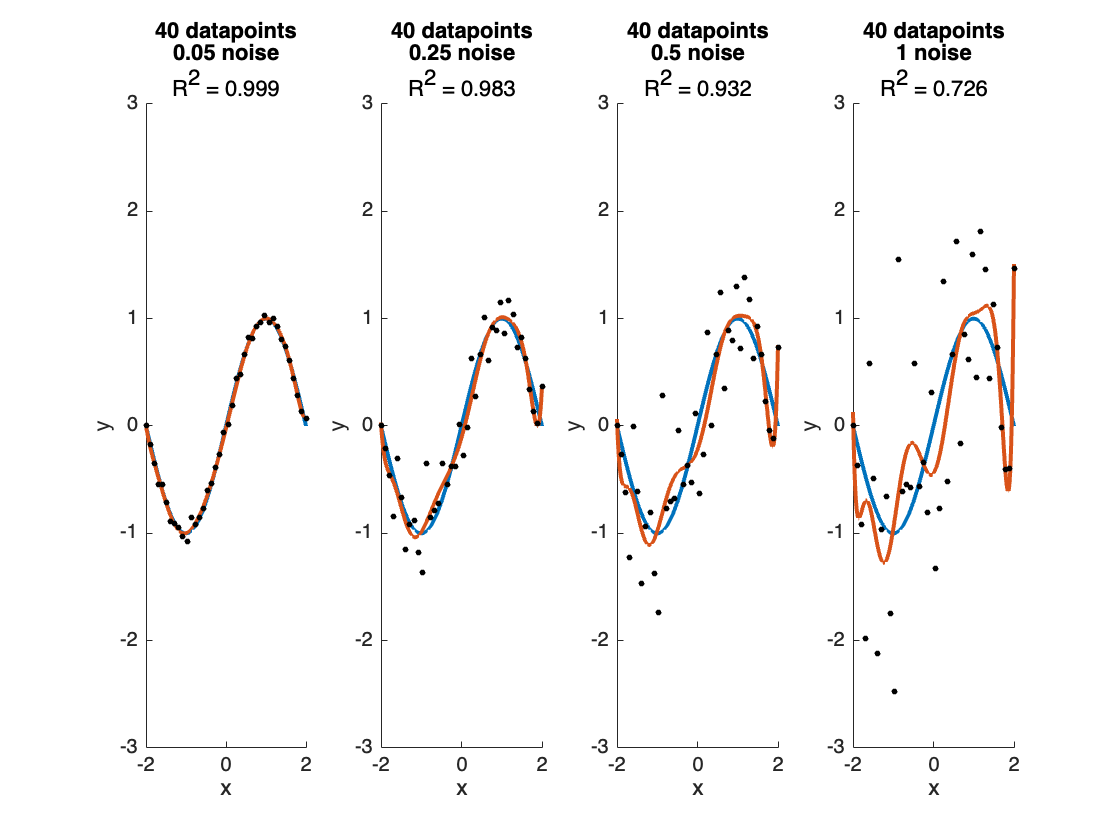

% Simulate data samples and fit models for different noise levels
nrObs = 40;
noiseLevelList = [.05,.25,.5,1];
figure
tiledlayout(1,length(noiseLevelList))

xSample = linspace(xMin,xMax,nrObs);
sampleIdx = ismember(round(xCurve,-log10(dx)),round(xSample,-log10(dx)));
polyRegSample = polyReg(:,sampleIdx);
noise = randn(1,nrObs);
for i = 1:length(noiseLevelList)
    noiseLevel = noiseLevelList(i);
    ySample = yCurveTrue(sampleIdx) + noise*noiseLevel;
    estBetas = regress(ySample',polyRegSample');
    yCurveEst = sum(estBetas.*polyReg);

    % Plot the true curve, data samples, and model estimate for each simulation
    nexttile
    hold on
    plot(xCurve,yCurveTrue,LineWidth=2)
    plot(xCurve,yCurveEst,LineWidth=2)
    scatter(xSample,ySample,10,'k','filled')
    ylim([-3,3])
    xlabel('x')
    ylabel('y')
    title({[num2str(nrObs),' datapoints'];[num2str(noiseLevel),' noise']})
    subtitle(['R^2 = ',num2str(Rsquared(yCurveEst,yCurveTrue),3)])
end

## Regularization simplifies models to reduce overfitting

Regularization is a process where a model is simplified in order to prevent overfitting.  In constraining models from overfitting to noise in training data, regularization improves the ability of models to generalize to unseen data, often bringing the model closer to a true representation of the system.  

There are a variety of different methods that perform regularization, including lasso (least absolute shrinkage and selection operator; L1 regularization), ridge regression (L2 or Tikhonov regularization), early stopping, principal component regression, and more.  This lesson will address how to use lasso and ridge regression, which are very common and relatively accessible.  They both work by introducing a penalty term to least squares optimization, imposing a cost on models for having larger coefficients.  For lasso, the penalty is given by $\lambda_1 *\sum_{i=1}^n {|\beta }_i |$, the summed absolute coefficient weights, while the ridge penalty is $\lambda_2 *\sum_{i=1}^n {\beta_i }^2$, the summed squared weights.  $\lambda_1$ and $\lambda_2$ are hyperparameters that scale the amount of regularization applied, their values usually determined using cross-validation.  The optimal models therefore balance minimizing residuals and minimizing coefficient weights (i.e. increasing simplicity).  Lasso and ridge regression are considered explicit regularization methods because they explicitly optimize simplicity, but many other methods impose regularization implicitly.

Note that regularization requires the regressor data to be z-scored (made to have mean=0 and SD=1) within each predictor variable.  This is because the scale of a variable's data will impact its coefficient weight (i.e. if a variable's data is doubled, then its resulting coefficient will be halved).  Since the regularized methods take into account the coefficient weights when applying penalties, each regressor's data should be made to be on the same scale.

We will start by comparing models estimated with multiple regressions to those estimated by lasso, which we can implement with the *lasso* function.

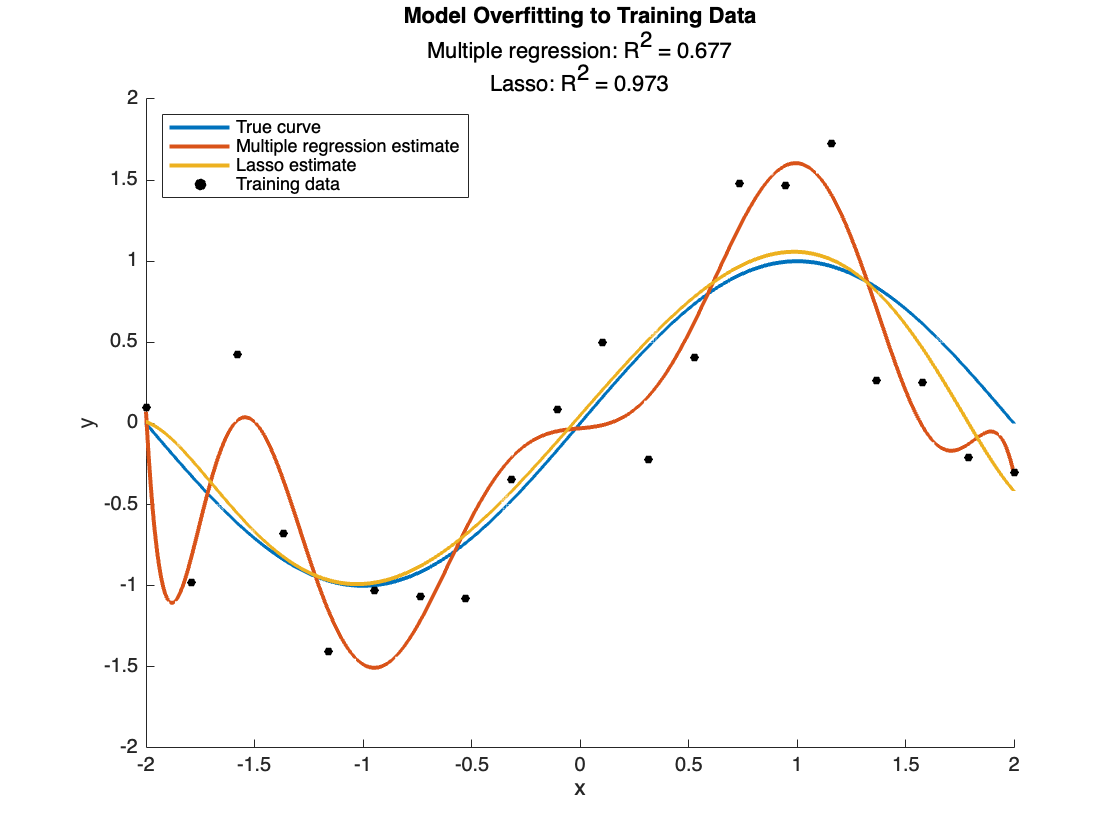

% Simulate data sample and fit models using multiple regression and lasso
nrObs = 20;
noiseLevel = .5;

xSample = linspace(xMin,xMax,nrObs);
sampleIdx = ismember(round(xCurve,-log10(dx)),round(xSample,-log10(dx)));
polyRegSample = polyReg(:,sampleIdx);
ySample = yCurveTrue(sampleIdx) + randn(1,nrObs)*noiseLevel;

% Fit model to the data sample using multiple regression
estBetas_multiReg = regress(ySample',polyRegSample');
yCurveEst_multiReg = sum(estBetas_multiReg.*polyReg); 

% Fit model to the data sample using lasso
[estBetas_lasso,~] = lasso(polyRegSample',ySample',Lambda=.01);
yCurveEst_lasso = sum(estBetas_lasso.*polyReg); 

% Plot the true curve, data samples, and model estimates
figure
hold on
plot(xCurve,yCurveTrue,LineWidth=2)
plot(xCurve,yCurveEst_multiReg,LineWidth=2)
plot(xCurve,yCurveEst_lasso,LineWidth=2)
scatter(xSample,ySample,20,'k','filled')
ylim([-2,2])
xlabel('x')
ylabel('y')
title('Model Overfitting to Training Data')
subtitle({['Multiple regression: R^2 = ',num2str(Rsquared(yCurveEst_multiReg,yCurveTrue),3)]; ...
    ['Lasso: R^2 = ',num2str(Rsquared(yCurveEst_lasso,yCurveTrue),3)]})
legend({'True curve';'Multiple regression estimate';'Lasso estimate';'Training data'},Location='northwest')

Moving on from polynomial curve fitting to linear model simulations, we can see that regularization yields coefficients that are more stable across simulations, more accurately reflect the true coefficients, and better generalize when predicting held-out data.  Our simulated data has few observations, noise, and collinearity (dependence) among predictor variables in order to show the especially large benefit of regularization in situations when plain regression does not perform well.

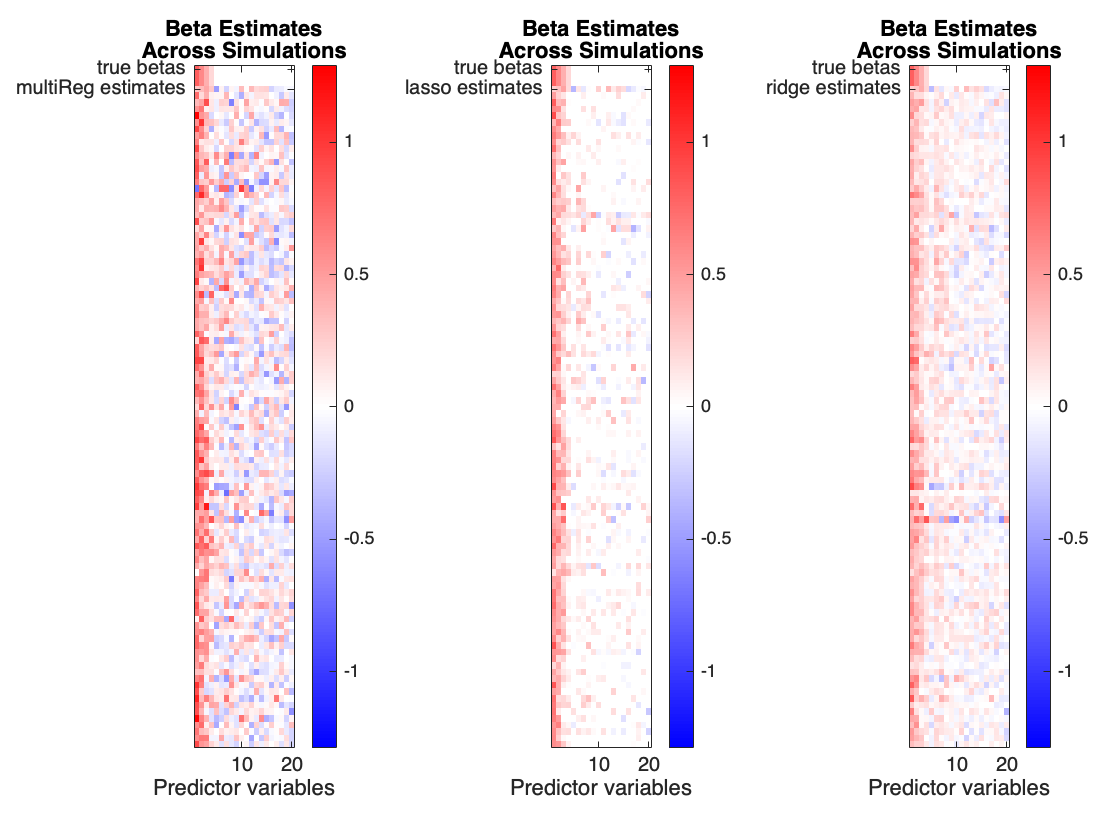

nrVars = 20; % Number of predictor variables
trueBetas = zeros(nrVars,1);
trueBetas(1:5) = [.8,.6,.4,.2,0]; % Designate true beta values
nrObs = 30; % Number of observations/datapoints
noiseLevel = .4; % Noise level in y data
nrRepeats = 100; % Number of simulations to run

% Simulate X and y data
X = randn(nrVars,nrObs,nrRepeats);
X(6:10,:,:) = X(6:10,:,:)*.5 + X(1:5,:,:)*.5; % Add some collinearity among regressors
X(11:15,:,:) = X(11:15,:,:)*.5 + X(6:10,:,:)*.5;
X(16:20,:,:) = X(16:20,:,:)*.5 + X(11:15,:,:)*.5;
y = sum(X.*trueBetas,1) + randn(1,nrObs,nrRepeats)*noiseLevel;
X = X + randn(nrVars,nrObs,nrRepeats)*noiseLevel; % Add measurement noise to regressors
XScaled = zscore(X,0,2); % Z-score the regressors (X data) 

% Preallocate variables
models = {'multiReg','lasso','ridge'};
clear estBetas
for m = 1:length(models)
    estBetas.(models{m}) = nan(nrVars,nrRepeats);
    simToTrueBetas.(models{m}) = nan(1,nrRepeats);
    heldOutPred.(models{m}) = nan(nrRepeats,nrRepeats);
end

for i = 1:nrRepeats
    % Fit regression model
    estBetas.multiReg(:,i) = regress(y(:,:,i)',XScaled(:,:,i)');

    % Fit lasso model
    [B,FitInfo] = lasso(XScaled(:,:,i)',y(:,:,i)',CV=10,Intercept=false,Standardize=false);
    estBetas.lasso(:,i) = B(:,FitInfo.IndexMinMSE);

    % Fit ridge model
    [B,FitInfo] = ridgeCV(XScaled(:,:,i)',y(:,:,i)',CV=10,nrSweeps=3);
    estBetas.ridge(:,i) = B(:,FitInfo.IndexMinMSE);

    % Calculate similarity between each set of estimated betas and true betas
    for m = 1:length(models)
        tmp = corrcoef(trueBetas,estBetas.(models{m})(:,i));
        simToTrueBetas.(models{m})(i) = tmp(1,2);
    end

    % Calculate prediction accuracy for other simulations' data
    for j = 1:nrRepeats
        if j==i
            continue
        end
        for m = 1:length(models)
            heldOutPred.(models{m})(i,j) = Rsquared(sum(XScaled(:,:,j).*estBetas.(models{m})(:,i)),y(:,:,j));
        end
    end
end

% Use imagesc to plot coefficient values
figure
tiledlayout(1,3)
cLimMax = max(abs([trueBetas,estBetas.multiReg,estBetas.lasso,estBetas.ridge]),[],'all');
cLimMin = -cLimMax;
rowsOfTrueBetas = 3;
for m = 1:length(models)
    nexttile
    imagesc([repmat(trueBetas,1,rowsOfTrueBetas),estBetas.(models{m})]',[cLimMin cLimMax])
    colormap(blueWhiteRedColormap())
    colorbar
    yticks([1,rowsOfTrueBetas+1])
    yticklabels({'true betas',[models{m},' estimates']})
    title({'Beta Estimates';'Across Simulations'})
    xlabel('Predictor variables')
end

% Print results
for m = 1:length(models)
    if m==1; fprintf('Stability of coefficients---'); end
    fprintf([models{m},': mean SD = ',num2str(mean(std(estBetas.(models{m}),0,2))),'\n'])
end

Stability of coefficients---

multiReg: mean SD = 0.23598
lasso: mean SD = 0.087036
ridge: mean SD = 0.11906


for m = 1:length(models)
    if m==1; fprintf('Similarity of estimated to true betas---'); end
    fprintf([models{m},': mean r = ',num2str(mean(simToTrueBetas.(models{m}))),'\n'])
end

Similarity of estimated to true betas---

multiReg: mean r = 0.61529
lasso: mean r = 0.84706
ridge: mean r = 0.71262


for m = 1:length(models)
    if m==1; fprintf('Prediction of held-out data---'); end
    fprintf([models{m},': mean R^2 = ',num2str(mean(heldOutPred.(models{m}),"all","omitnan")),'\n'])
end

Prediction of held-out data---

multiReg: mean R^2 = 0.066658
lasso: mean R^2 = 0.55428
ridge: mean R^2 = 0.4689


## Lasso vs ridge regression

Lasso and ridge regression are both common regularization methods, and as explained above, they penalize model coefficient weights differently.  This results in some differences in their model estimates.  Lasso is known to produce sparse models, bringing unnecessary coefficients to zero while preserving the variables that are informative.  This occurs because it penalizes the absolute values of coefficients.  Ridge regression, on the other hand, penalizes the squares of coefficients.  Larger coefficients will therefore be subject to a larger penalty and will face greater pressure to decrease their weights.  Very small coefficients will meanwhile face less pressure to shrink, and their penalties will often become negligible before their weights actually reach zero.  In this way, ridge regression produces a more diffuse pattern of model coefficients, with smaller weights spread across a larger number of explanatory variables.  This may be an issue in the presence of collinearity or dependence among regressors, as the model may choose to spread influence to lesser variables in order to avoid giving the best predictor a higher weight.  Still, ridge regression can be advantageous in allowing more low-weighted variables to remain.  Another option is to apply elastic net, which combines uses both L1 and L2 penalties.  This can be implemented with the *lasso* function by setting the *Alpha* option to the desired L1:L2 ratio.

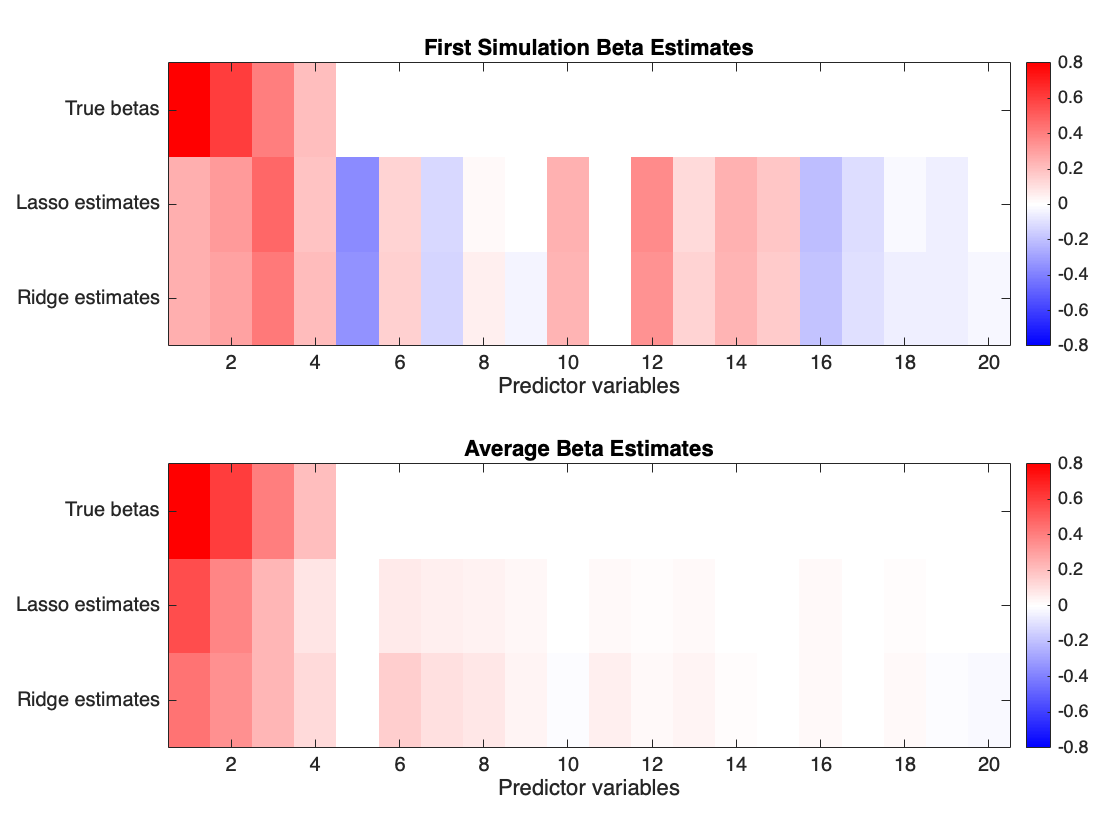

% Use imagesc to plot coefficient values
figure
tiledlayout(2,1)

nexttile
cLimMax = max(abs([trueBetas;estBetas.lasso(:,1);estBetas.ridge(:,1)]));
cLimMin = -cLimMax;
imagesc([trueBetas,estBetas.lasso(:,1),estBetas.ridge(:,1)]',[cLimMin cLimMax])
colormap(blueWhiteRedColormap())
colorbar
yticks([1,2,3])
yticklabels({'True betas','Lasso estimates','Ridge estimates'})
title('First Simulation Beta Estimates')
xlabel('Predictor variables')

nexttile
cLimMax = max(abs([trueBetas;mean(estBetas.lasso,2);mean(estBetas.ridge,2)]));
cLimMin = -cLimMax;
imagesc([trueBetas,mean(estBetas.lasso,2),mean(estBetas.ridge,2)]',[cLimMin cLimMax])
colormap(blueWhiteRedColormap())
colorbar
yticks([1,2,3])
yticklabels({'True betas','Lasso estimates','Ridge estimates'})
title('Average Beta Estimates')
xlabel('Predictor variables')

The effects of lasso and ridge (and elastic net) on the coefficients is often explained geometrically using the following figure:

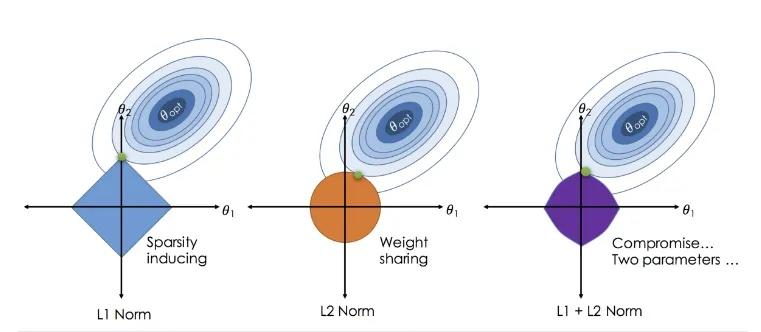

Every location on the plot represents a possible combination of model coefficients for two variables, their weights varying along the x and y axes.  The ellipse shows the coefficient combinations that optimize ordinary least squares (OLS).  The coefficient weights at the very center of the ellipse minimize the OLS term and would be the optimal beta estimates for a basic regression model.  The diamond, circle, and rounded diamond represent the contour shape of the penalty terms for lasso, ridge, and elastic net regularization.  The penalty is zero at the origin and increases as the coefficients move away from zero, with all combinations along a contour receiving the same penalty.  To best reduce the penalty, the coefficients will decrease in the direction perpendicular to the contour.  However, this has to be balanced to limit the increase in OLS term.  Increasing the lambda hyperparameter will increase the penalty, strengthening the pull of coefficients toward zero.  

The figure is recreated below.  The blue dot represents the optimal coefficients for OLS only, and the red dot is the optimal coefficients for a given value of lambda.  The red dotted line shows the trajectory of optimal coefficients as lambda is increased from zero.

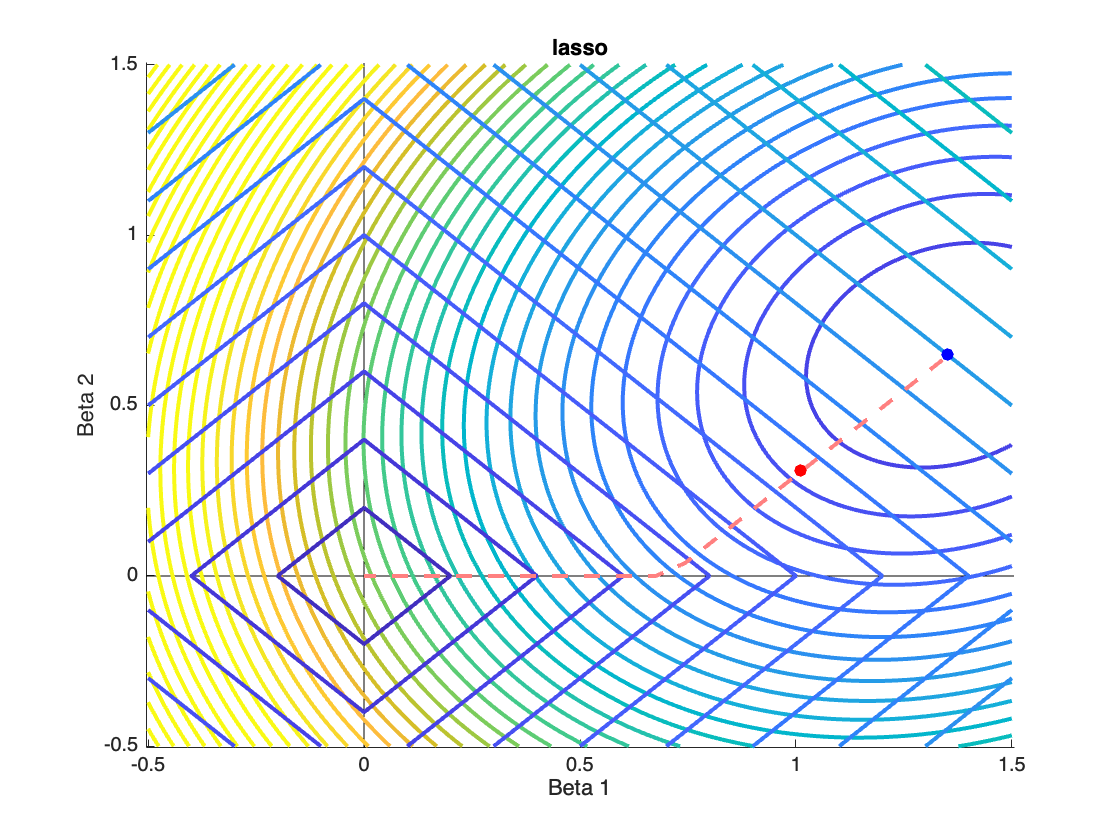

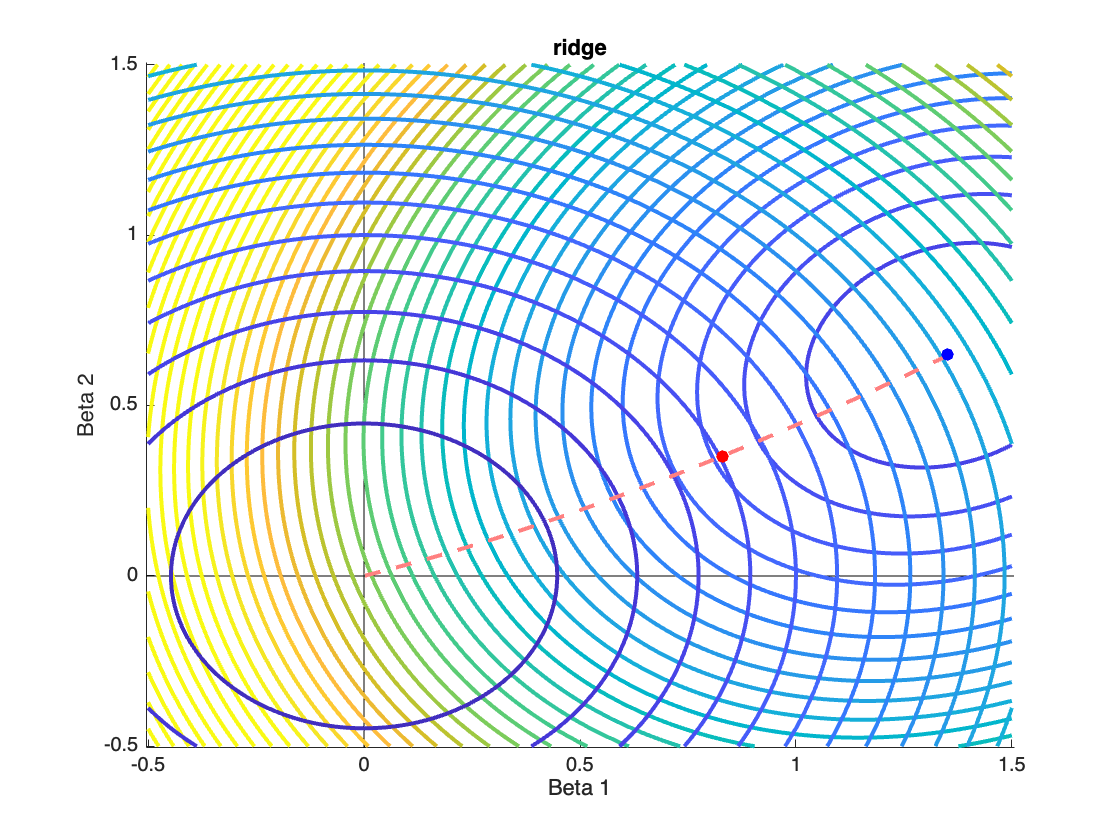

% Map model cost for each combination of beta coefficients
nrVars = 2;
nrObs = 10;
noiseLevel = .25;
trueBetas = [1.2;.8];
lambda = 5; % Lasso and ridge hyperparameter
moreLambdas = 10.^(-2:.05:5); % To plot trajectory of betas

testMinBeta = -.5;
testMaxBeta = 1.5;
dBeta = .01;
testBetas = testMinBeta:dBeta:testMaxBeta;

% Simulate X and y data
X = randn(nrVars,nrObs);
y = sum(trueBetas.*X) + randn(1,nrObs)*noiseLevel;
X = X + randn(nrVars,nrObs)*noiseLevel; % Add measurement noise to X
XScaled = zscore(X,0,2);

% Preallocate variables
models = {'multiReg','lasso','ridge'};
for m = 1:length(models)
    loss.(models{m}) = nan(length(testBetas),length(testBetas));
    penalty.(models{m}) = nan(length(testBetas),length(testBetas));
end

% Loop through beta weights for both variables
for b1 = 1:length(testBetas)
    for b2 = 1:length(testBetas)
        betas = [testBetas(b1);testBetas(b2)];

        % Summed squares of model residuals
        leastSqrs = sum((y - sum(betas.*XScaled)).^2);

        % Regularization penalty
        penalty.multiReg(b1,b2) = 0;
        penalty.ridge(b1,b2) = lambda*sum(betas.^2);
        penalty.lasso(b1,b2) = lambda*sum(abs(betas));

        % Total loss at given beta weights
        for m = 1:length(models)
            loss.(models{m})(b1,b2) = leastSqrs + penalty.(models{m})(b1,b2);
        end
    end
end

% Find the beta weights that minimize loss
for m = 1:length(models)
    [minVal,minIdx] = min(loss.(models{m}),[],'all');
    [b1,b2] = ind2sub([length(testBetas),length(testBetas)],minIdx);
    bestBetas.(models{m}) = [testBetas(b1);testBetas(b2)];
end

% Find optimal betas (more quickly) for different values of lambda
[bestBetasByLambda.lasso,~] = lasso(XScaled',y',Lambda=moreLambdas,Intercept=false,Standardize=false);
[bestBetasByLambda.ridge,~] = ridgeCV(XScaled',y',Lambda=moreLambdas);

% Plot model loss as contour maps
vMin = 0;
vMax = max([loss.multiReg,loss.ridge,loss.lasso],[],'all')*.5;
for m = 2:length(models)
    figure
    hold on
    % Plot x and y axes
    plot([testMinBeta-(dBeta/2),testMaxBeta+(dBeta/2)],[0,0],'black')
    plot([0,0],[testMinBeta-(dBeta/2),testMaxBeta+(dBeta/2)],'black')

    % Plot separate contour lines for least squares and regularization penalties
    contour(testBetas,testBetas,loss.multiReg',LevelStep=1,LevelStepMode='manual',LineWidth=2)
    contour(testBetas,testBetas,penalty.(models{m})',LevelStep=1,LevelStepMode='manual',LineWidth=2)
    
    % Plot the trajectory of optimal betas with increasing lambda 
    plot(bestBetasByLambda.(models{m})(1,:),bestBetasByLambda.(models{m})(2,:),'--',Color=[1,.5,.5],LineWidth=2)

    % Mark optimal betas for unregularized model
    scatter(bestBetas.multiReg(1),bestBetas.multiReg(2),40,'bo','filled')
    
    % Mark optimal betas for this model
    scatter(bestBetas.(models{m})(1),bestBetas.(models{m})(2),40,'ro','filled')
    
    xlim([testMinBeta-(dBeta/2),testMaxBeta+(dBeta/2)])
    ylim([testMinBeta-(dBeta/2),testMaxBeta+(dBeta/2)])
    clim([vMin,vMax])
    xlabel('Beta 1')
    ylabel('Beta 2')
    title(models(m))
end

## Hyperparameter selection

Regularization often requires the selection of at least one hyperparameter, the choice of which can greatly impact the resulting model estimates.  The optimal hyperparameter values therefore should be found with cross-validation before estimating the final model.  The hyperparameters for lasso and ridge regression are λ1 and λ2, respectively, (*Lambda* in the *Lasso* and *Ridge* functions) and they scale the lasso and ridge penalty terms. Lambda values of zero would coincide with unregularized multiple regression, and higher values would lead to a greater degree of regularization.  Elastic net requires two hyperparameters, often one lambda term for overall penalty and one that provides the ratio of L1 to L2 penalties (*Alpha* in the *Lasso* function).  If the hyperparameter(s) of any method does not induce enough regularization, then the model will still overfit to noise, but if the hyperparameter induces too much regularization, then the model may discard relevant information. The optimal value would balance these two tendencies. 

Optimal hyperparameters are often determined using cross validation.  A model is fit to a subset of training data for a range of hyperparameter values, and each model is then tested on the testing subset of data.  Model performance can be measured using mean squared error (MSE), R^2, loglikelihood, or a number of other metrics.  The hyperparameter that yields best performance is then used to fit the model to all data.  

(Note that a model fit with fewer datapoints will often benefit from a larger degree of regularization than a model fit with more datapoints of otherwise similar data.  For this reason, I'd recommend using a similar amount of data in the training set as is available in the full dataset, as using a much smaller training set could advise a hyperparameter value that induces more regularization than is optimal for the full dataset.  I.e. I'd recommend using 10-fold cross validation over split-half or maybe even 5-fold, since the first would assess models trained on 90% of the total number of datapoints while the others would assess models trained on only 50% or 80%.)

The Matlab function *lasso* has a built-in option (*CV=_*) to perform cross validation on a range of lambda values.  It can test a range of values supplied by the user (*Lambda=_*) or determine a range of values on its own.  It measures model performance using MSE.  The original *ridge* function does not have this option to perform cross validation, and any implementations of ridge regression in this script were calling a custom function (ridgeCV.m) that adds some cross validation capabilities.  The following code demonstrates finding the optimal hyperparameters for lasso separately using MSE and R^2.

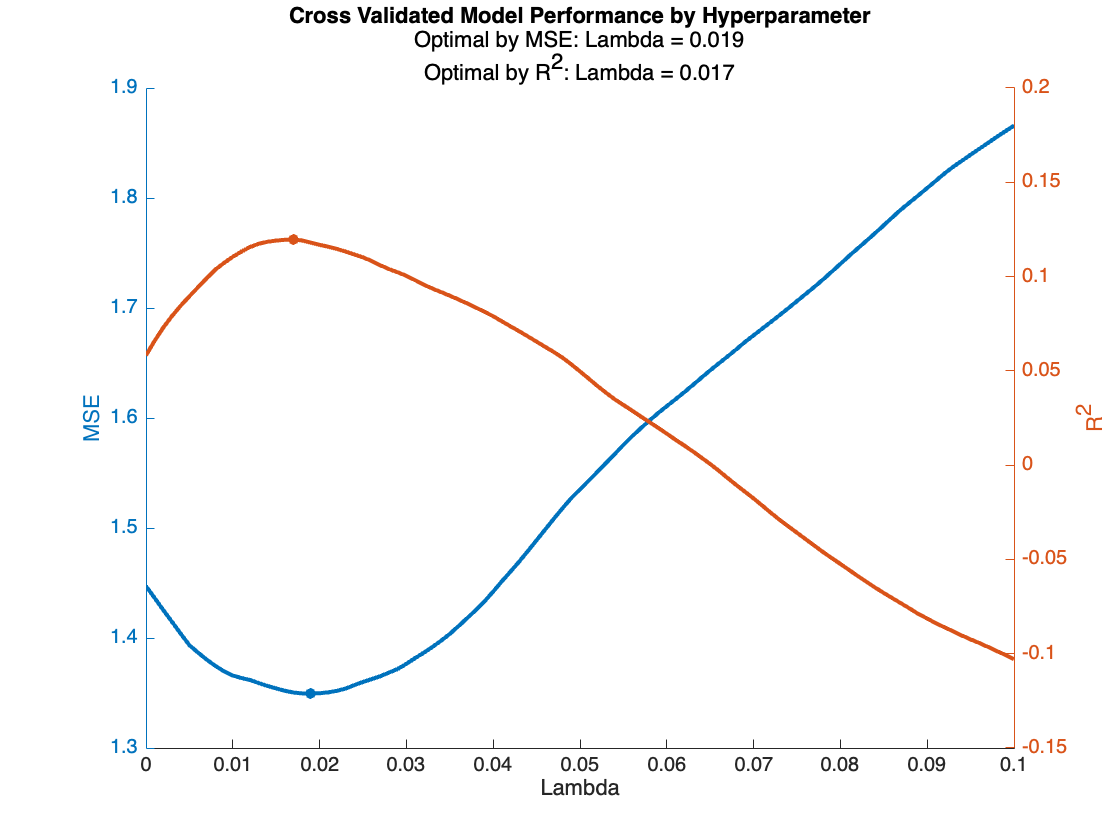

% Simulate data for testing hyperparameters
nrVars = 50; % Number of predictor variables
nrObs = 100; % Number of observations/datapoints
noiseLevel = .5; % Noise level in y data

% Randomly set true beta values
trueBetas = rand(nrVars,1); % Chosen from uniform distribution, values between 0 and 1
trueBetas(trueBetas<.5) = 0; % Set ~50% to zero
trueBetas = trueBetas*.5; % Scale the remaining betas by half

% Simulate X and y 
X = randn(nrVars,nrObs);
y = sum(X.*trueBetas,1) + randn(1,nrObs)*noiseLevel;
X = X + randn(nrVars,nrObs)*noiseLevel; % Add measurement noise to regressors
XScaled = zscore(X,0,2); % Z-score the regressors (X data) 

% Lambda values to test
testLambdas = 0:.001:.1;
nrLambdas = length(testLambdas);

% Number of folds for k-fold cross validation
nrFolds = 10;

%%% MSE
% Get average MSEs for each lambda
[~,FitInfo] = lasso(XScaled',y',Lambda=testLambdas,CV=nrFolds);
meanMSE = FitInfo.MSE;
% Lambda with minimum MSE is already recorded
bestLambdaMSEIdx = FitInfo.IndexMinMSE;
bestLambdaMSE = FitInfo.LambdaMinMSE;

%%% R^2
R2 = nan(nrLambdas,nrFolds);

% Create a boolean array to divide observations between CV folds
kFoldsIdx = false(nrObs,nrFolds);
k = 1;
for i = 1:nrObs
    kFoldsIdx(i,k) = true;
    if k == nrFolds
        k = 1;
    else
        k = k+1; 
    end
end

% Loop through CV folds
for k = 1:nrFolds
    % Fit models to training data for each fold (training datapoints = where kFoldsIdx(k) is false)
    betasCV = nan(nrVars,1,nrLambdas);
    [betasCV(:,:,:),~] = lasso(XScaled(:,~kFoldsIdx(:,k))',y(:,~kFoldsIdx(:,k))',Lambda=testLambdas);
    
    % Extend betasCV array along the 2nd dimenson (nrObs in test fold)
    tmpBetasCV = repmat(betasCV,1,sum(kFoldsIdx(:,k)),1);
    % Extend XScaled array along the 3nd dimenson (nrLambdas)
    tmpXScaled_test = repmat(XScaled(:,kFoldsIdx(:,k)),1,1,nrLambdas);
    % Predict y values for the testing data, from the model betas (training data) and testing data X values
    yPred = sum(tmpBetasCV .* tmpXScaled_test, 1);

    % Extend y array along the 3nd dimenson (nrLambdas)
    tmpY_test = repmat(y(:,kFoldsIdx(:,k)),1,1,nrLambdas);
    % Calculate R^2 between the actual and predicted y values, within the CV fold, for all lambdas
    R2(:,k) = Rsquared(yPred,tmpY_test,dim=2);
end

meanR2 = mean(R2,2);

% Find lambda with highest R^2
bestLambdaR2Idx = find(meanR2 == max(meanR2),1);
bestLambdaR2 = testLambdas(bestLambdaR2Idx);

%%% Plot the results 
figure
hold on
yyaxis left
plot(testLambdas,meanMSE,LineWidth=2)
scatter(bestLambdaMSE,meanMSE(bestLambdaMSEIdx),30,'o','filled')
ylabel('MSE')
xlabel('Lambda')
yyaxis right
plot(testLambdas,meanR2,LineWidth=2)
scatter(bestLambdaR2,meanR2(bestLambdaR2Idx),30,'o','filled')
ylabel('R^2')
title('Cross Validated Model Performance by Hyperparameter')
subtitle({['Optimal by MSE: Lambda = ',num2str(bestLambdaMSE)]; ...
    ['Optimal by R^2: Lambda = ',num2str(bestLambdaR2)]})